h = linspace(0, 100e3);

myfigure('Физическая модель: Моргунов')

ans =   Figure (1: Физическая модель: Моргунов) with properties:

      Number: 1
        Name: 'Физическая модель: Моргунов'
       Color: [0.9400 0.9400 0.9400]
    Position: [360 502 560 420]
       Units: 'pixels'

  Show all properties


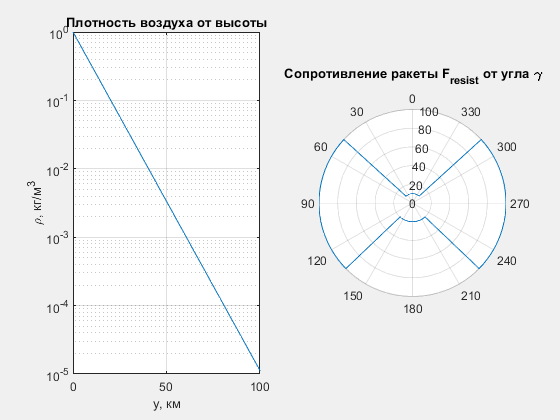

subplot(121);
semilogy(h /1000, airDensity(h));
grid on;
title('Плотность воздуха от высоты');
xlabel('y, км');
ylabel('\rho, кг/м^3');

subplot(122);
gamma = linspace(0, 2*pi);
polarplot(gamma, abs(resistanceForce(1, 1, gamma)));
set(gca, 'ThetaZeroLocation', 'top');
title('Сопротивление ракеты F_{resist} от угла \gamma');

function f = myfigure(name, varargin)
    f = figure( ...
        'Visible', 'on', ...
        'NumberTitle', 'off', ...
        'Name', name, ...
        varargin{:} ...
        );
end